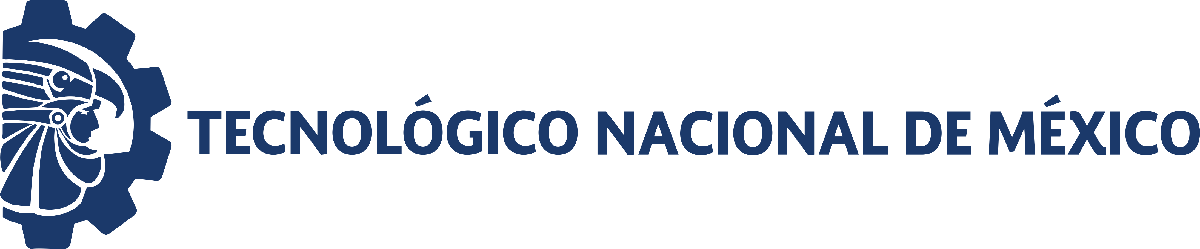                                 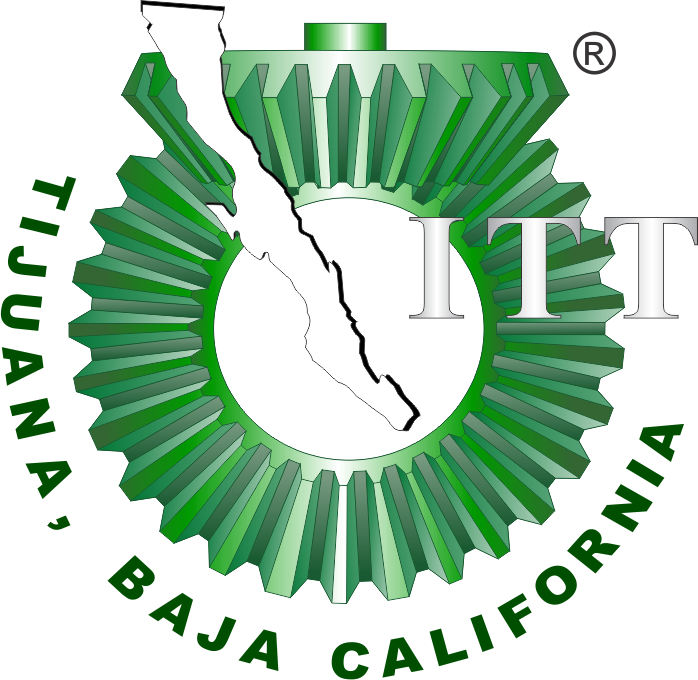

# Práctica 1: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Ian Enrique Estrada Castillo

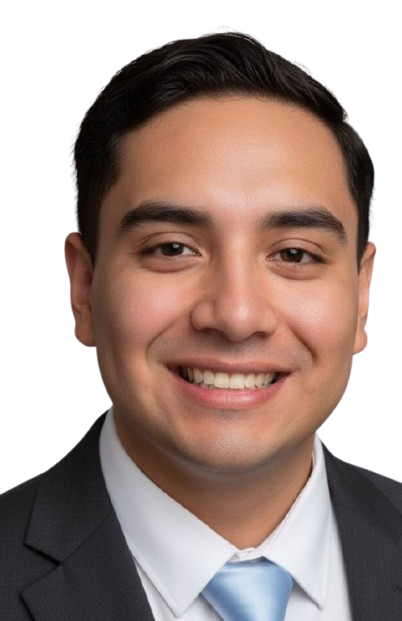

Número de control: 22211753

Correo institucional: l22211753**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

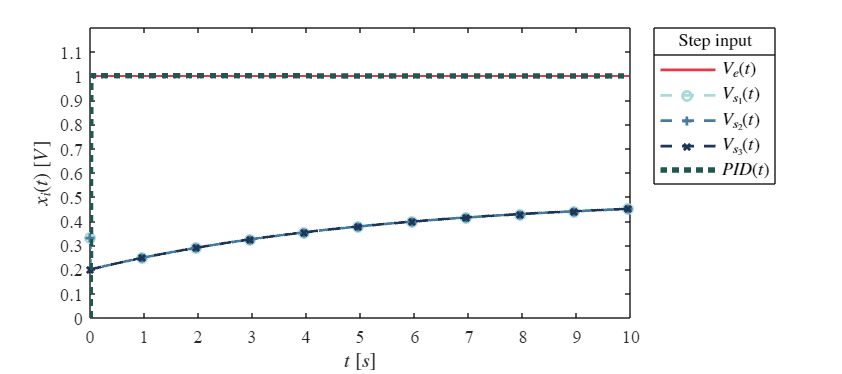

Signal = 'Step';
set_param('SistemaA/S1','sw','1');
set_param('SistemaA/Ve(t)','sw','1');
X1 = sim(file,parameters);
plotsignals(X1.t,X1.Ve,X1.Vs1,X1.Vs2,X1.Vs3,X1.PID,Signal);

## Respuesta al impulso

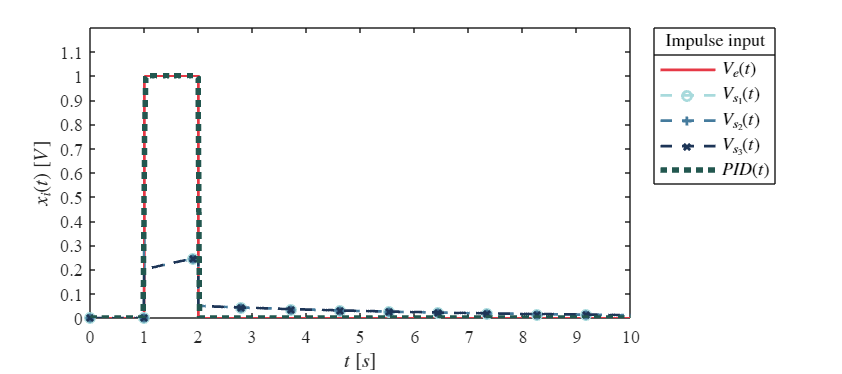

Signal = 'Impulse';
set_param('SistemaA/S1','sw','0');
set_param('SistemaA/Ve(t)','sw','1');
X2 = sim(file,parameters);
plotsignals(X2.t,X2.Ve,X2.Vs1,X2.Vs2,X2.Vs3,X2.PID,Signal);

## Respuesta a la rampa

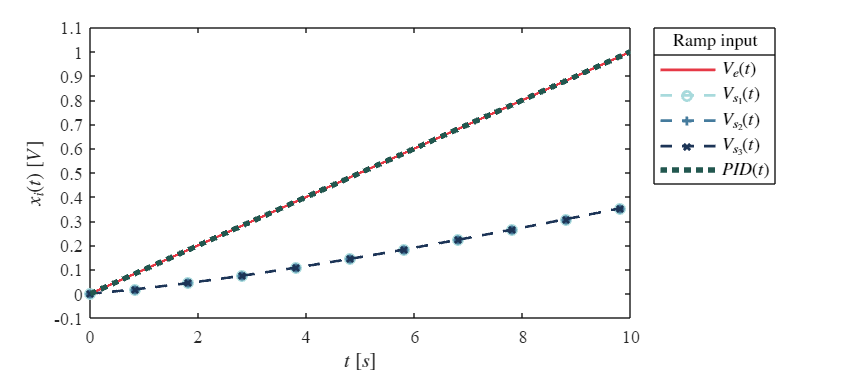

Signal = 'Ramp';
set_param('SistemaA/S2','sw','1');
set_param('SistemaA/Ve(t)','sw','0');
X3 = sim(file,parameters);
plotsignals(X3.t,X3.Ve,X3.Vs1,X3.Vs2,X3.Vs3,X3.PID,Signal);

## Respuesta a la función sinusoidal

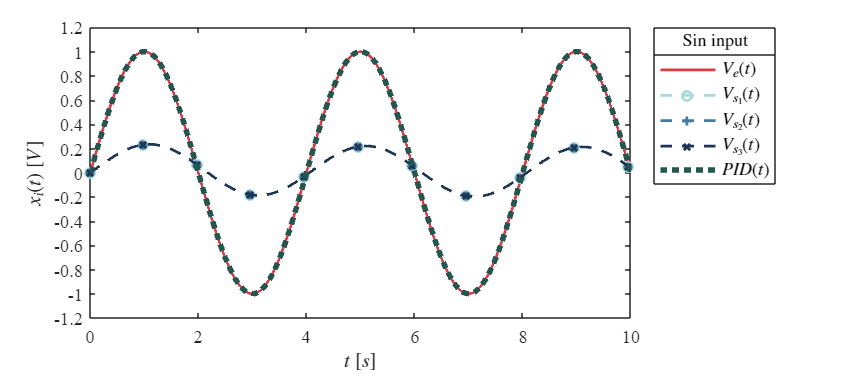

Signal = 'Sin';
set_param('SistemaA/S2','sw','0');
set_param('SistemaA/Ve(t)','sw','0');
X4 = sim(file,parameters);
plotsignals(X4.t,X4.Ve,X4.Vs1,X4.Vs2,X4.Vs3,X4.PID,Signal);

## Función: Respuesta a las señáles

function plotsignals(t,Ve,Vs1,Vs2,Vs3,PID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,Ve,'-',t,Vs1,'--o',t,Vs2,'--+',t,Vs3,'--x',t,PID,':',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5), 'LineWidth',3); 
    L = legend('$V_e(t)$','$V_{s_1}(t)$','$V_{s_2}(t)$','$V_{s_3}(t)$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    if Signal == "Step" || Signal == "Impulse"
        xlim([0,10]); xticks(0:1:10);
        ylim([0,1.2]); yticks(0:0.1:10);
    
    elseif Signal == "Ramp"
        ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    elseif Signal == "Sin"
        ylim([-1.2,1.2]); yticks(-1.2:0.2:2);
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

    
end